# 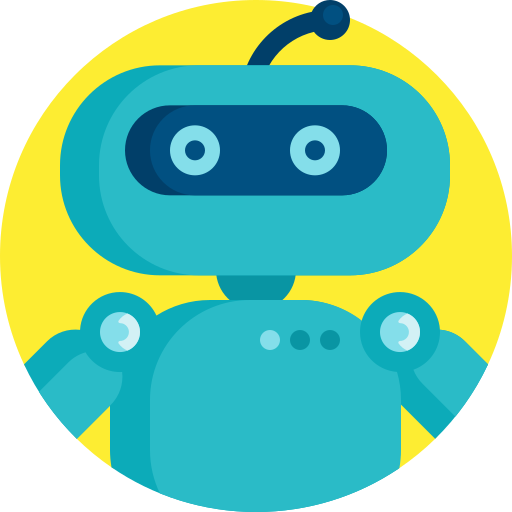

# **MEC4127F: Introduction to Robotics**

# Chapter 9: Quadcopter dynamics

## 9.1 Introduction

Up until this point in the course we have only considered the kinematics of robots. In other words, we have only assessed how velocity and/or acceleration affects the motion of a rigid-body robot. In this Chapter we will introduce the dynamics of conventional quadcopters. In particular, we will explore both the rotational and translational dynamics of the UAV in question, as well as how they relate to the pose of the robot. Unlike kinematic modelling, dynamic modelling considers the forces and torques acting on a body, as well as the associated masses and mass moment of inertia that contribute to the overall acceleration behaviour of the platform.

### 9.1.1 Types of quadcopters

As the name suggests, quadcopters make use of four motor-propeller subsystems to affect motion on the robot's rigid body. While a multitude of quadcopter frame designs exist in literature, the prevailing two approaches tend to be:

- X-shaped

- H-shaped

These are exemplified in Figure 9.1 below.

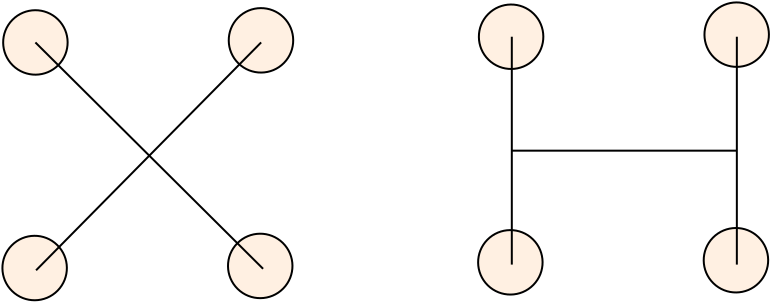

**Figure 9.1:** Comparison of X-shaped and H-shaped quadcopter frame.

We will focus on the X-shaped design in this course. However, the concepts developed in **Chapter 9** and **Chapter 10 **can be extended to any rigid-body quadcopter frame design.

## 9.2 Reference frames

As with the previous robots under consideration in this course, we have the choice of where to locate $\{B\}$ on the robot body. Locating the origin of $\{B\}$ such that it is coincident with the centre of mass simplifies the modelling approach significantly, but we can still choose the orientation of $\{B\}$ with respect to the robot body. Common approaches are to either

- align the $\hat{\bf x}_B$ and $\hat{\bf y}_B$ axes such that they are parallel to the rotor arms (see Figure 9.2 left), or

- align the $\hat{\bf x}_B$ and $\hat{\bf y}_B$ axes such that the axes have been rotated by $45^\circ$ about $\hat{\bf z}_B$ away from the rotor arms (see Figure 9.2 right).

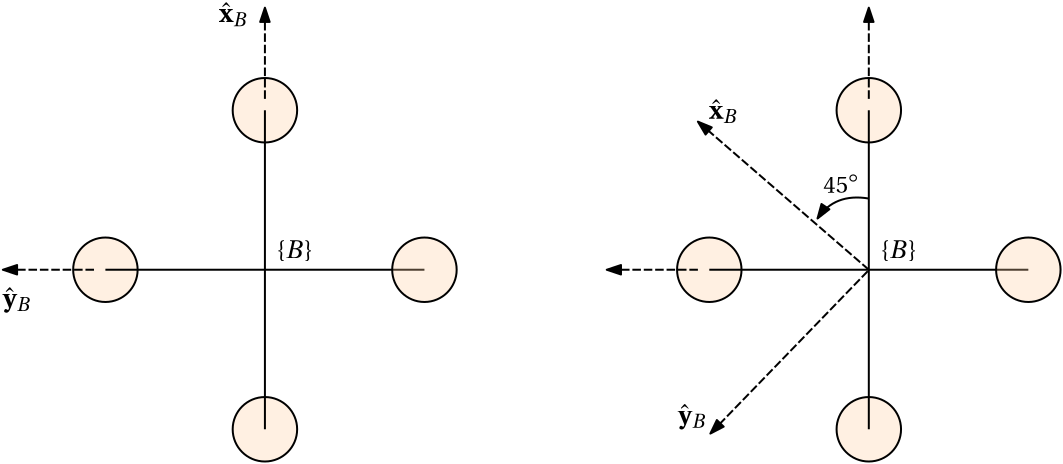

**Figure 9.2:** Choice of $\{B\}$ such that principal axes are parallel to rotor arms (left), and rotated away from rotor arms (right).

There are many benefits in using the latter approach, such as increasing rolling/pitching moments, and also offering failure redundancy during motor/propeller failures. However, to simplify matters, we will make use of the first option, and consider the positive $\hat{\bf x}_B$-axis to indicate "forward" direction of the quadcopter. Again, this has no fundamental alteration to the methodology given in the subsequent sections.

### 9.2.1 Navigation frames

The configuration shown in Figure 9.3 (left) is often referred to as **North-West-Up** (NWU), which implies that $\hat{\bf x}_B$ points northwards (and is thought of as "forwards" to the UAV), $\hat{\bf y}_B$ points westwards (or "leftwards"), and $\hat{\bf z}_B$ points upwards. 

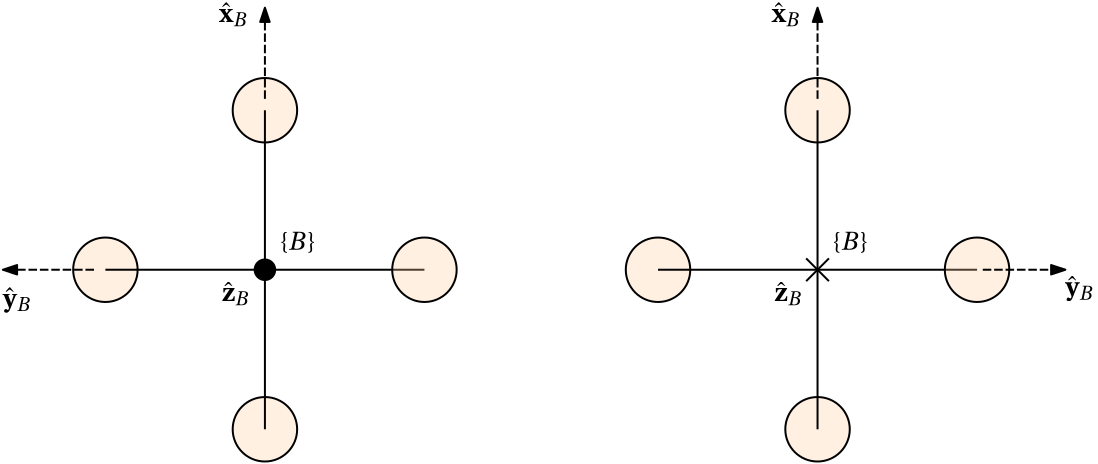

**Figure 9.3:** North-West-Up convention (left) and North-East-Down convention (right).

It is common practice to ensure that the configuration of $\{B\}$ and $\{W\}$ match during initialisation of the system, implying a null rotation. In fact, all our prior work with $\{W\}$ has been implicitly using the configuration of NWU, as positive motion in $\hat{\bf z}_B$ results in upwards motion away from the ground — not towards it.

As seen in Figure 9.3 (right), another popular configuration used in aerospace is **North-East-Down** (NED), where the $\hat{\bf z}_B$-axis points towards the ground during a null rotation, with $\hat{\bf y}_B$ pointing eastwards instead of westwards ($\hat{\bf x}_B$ remains unchanged). NWU and NED are therefore related by a $180^\circ$ rotation about $\hat{\bf x}_B$. There are benefits to this approach in terms of how rotational angle polarity is described. However, we will predominantly make use of NWU in this course.

## 9.3 Rotor thrust and torque equations

The motor thrust and torque equations are based on blade element theory and momentum theory, which will not be explored in this course. Instead, the closed-form result will be provided and applied. 

### 9.3.1 Rotor speeds

With reference to Figure 9.4, the quadcopter possesses four motor-propeller subsystems (hereinafter referred to as rotors) that are located at the extremities of the rigid body frame, with the rotational velocity of rotor $i$ given by $\overline\omega_i$. Note that the sign of $\overline\omega_i$ is dictated by right-hand rule. Each motor is driven by an electronic speed controller (ESC) that controls the rotational velocity of the propellers.

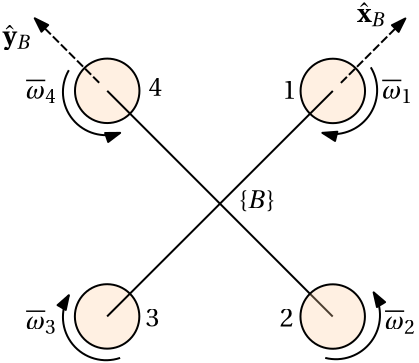

**Figure 9.4:** Top-down view of quadcopter with frame $\{B\}$ shown. Motor-propeller enumerations and directions are also shown.

The purpose of the four rotors is to produce four independent thrusts and torques, which collectively create a thrust and moment vector that can be used to affect change to the rigid body. Based on the standard quadcopter approach, the rotors are configured such that that rotor thrust and torque act parallel (or anti-parallel) to $\hat{\bf z}_B$ (coming out the page in Figure 9.4).

The outrunner of each motor and the propellers will have non-negligible inertia, which means that one cannot command a desired rotor speed $\overline\omega_i^*$ and then instantaneously obtain it. Instead, there will be some transient period in which the actual rotor speed approaches the desired speed. This is often modelling using a first-order or second-order transfer function, along with some delay. However, for small-scale quadcopters, it is often adequate to make the assumption that the dynamics of the motor is sufficiently fast relative to the dynamics of the rigid body. We will follow suit here for the purposes of this course, albeit with minor consideration for non-instantaneous rotor speed production. Specifically, we will model the transfer behaviour from a desired rotor speed to actual rotor speed using a fixed delay. In the Laplace domain this is described by


$$\overline\omega_i(s)=\overline\omega_i^*(s)e^{-st_d},$$


where $t_d$ describes the delay period.

As shown in Figure 9.4, $\overline\omega_1$ and $\overline\omega_3$ have clockwise rotations (negative rotation about $\hat{\bf z}_B$) whereas $\overline\omega_2$ and $\overline\omega_4$ have anti-clockwise rotations (positive rotation about $\hat{\bf z}_B$). For full controllability of the quadcopter opposite rotors must have common rotational directions. In the case of Figure 9.4 this implies that $\overline\omega_1$ and $\overline\omega_3$ rotate in one direction and $\overline\omega_2$ and $\overline\omega_4$ rotate in the opposite direction.

Based on the propeller design and type of ESC capabilities, the rotor speeds are usually unidirectional. That is, the rotor speeds are in the range of


$$\left|\overline\omega_i\right| \in \left[0,\overline\omega_{lim}\right].$$


The control command sent to the ESC, usually in the form of a PWM signal, is the lowest level of the system. A mapping from the effective DC voltage applied to the motor and the rotor speed can then be used to relate desired speeds to desired ESC commands in an open-loop fashion. However, for sake of simplicity, we will assume that the rotor speeds can be directly controlled for now.

### 9.3.2 Rotor thrust equation

In the case of NWU axis convention, the the each rotor's thrust acts parallel $\hat{\bf z}_B$. Based on blade element theory and momentum theory, the thrust produced by rotor $i$ is approximately given by


$$f_i=\frac{1}{6}\rho c n C_L \overline\omega_i^2R^3,$$


where $\rho$ is the air density, $c$ is the average chord length of the propeller, $n$ is the number of propeller blades, $C_L$ is the lift coefficient, and $R$ is the radius of the propeller. The above-mentioned parameters remain constant within a limited flight volume, which allows us to group all known constants into a single coefficient, yielding the more compact form of


$$f_i=k_f\overline\omega_i^2,$$


where $k_f=\frac{1}{6}\rho c n C_L R^3$ is known as the thrust coefficient. Given that the rotors are unidirectional based on $\overline\omega_i \in \left[0,\overline\omega_{lim}\right]$, the rotor thrust will be bounded by


$$f_i \in \left[0,k_f\overline\omega^2_{lim}\right].$$


### 9.3.2 Rotor torque equation

Rotor torque experienced by the propellers is a result of aerodynamic drag and will be applied in the opposing direction to the propeller angular velocity. As such, the rotor torque will act parallel or anti-parallel to $\hat{\bf z}_B$ depending the direction of rotation of the propellers. The torque produced by rotor $i$ is approximately given by


$$\tau_i=\left(-1\right)^{i+1}\frac{1}{8}\rho c n C_D \overline\omega_i^2R^4,$$


where $C_D$ is the drag coefficient of the propeller, and the term $\left(-1\right)^{i+1}$ is used to indicate the torque direction about $\hat{\bf z}_B$, which is anti-parallel to $\overline\omega_i$. The compact form of the rotor torque equation is given by


$$\tau_i=\left(-1\right)^{i+1}k_\tau\overline\omega_i^2,$$


where $k_\tau=\frac{1}{8}\rho c n C_D R^3$ is referred to as the torque coefficient. Given that the rotors are unidirectional based on $\overline\omega_i \in \left[0,\overline\omega_{lim}\right]$, the rotor torque will be bounded by


$$\left|\tau_i\right| \in \left[0,k_\tau\overline\omega^2_{lim}\right].$$


## 9.4 Attitude dynamics

The attitude dynamics describe the low-level behaviour of the quadcopter. As shown later, the translational dynamics are dictated by the attitude dynamics, which means that capturing the transient behaviour with sufficient fidelity is necessary to understand and (eventually) autonomously control a quadcopter in flight.

### 9.4.1 Torque vector

We begin by defining the controllable **torque vector** acting on the quadcopter, which is also known as the control moment. With reference to Figure 9.5, the thrust produced by each rotor also causes a moment on the rigid body, based on 


$$m_i = lf_i,$$


where $l$ is the (common) lever arm distance from the centre of mass to the rotor centre. 

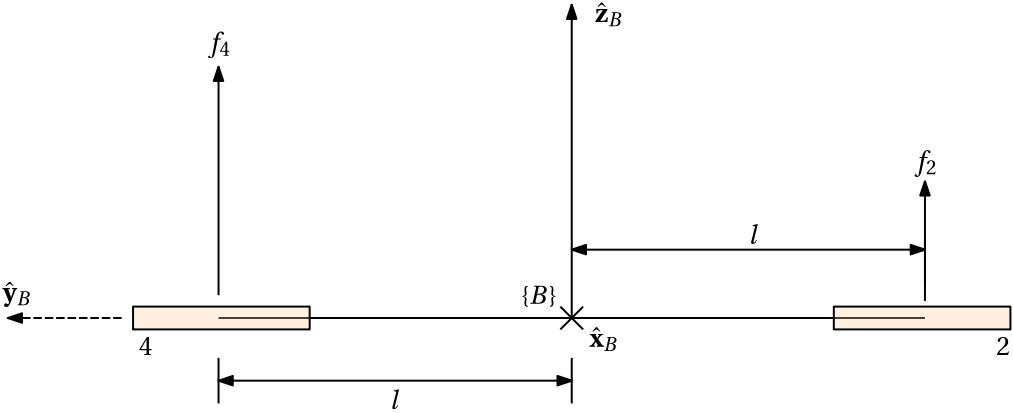

**Figure 9.5:** Side view of quadcopter with frame $\{B\}$ shown, as well as forces produced by rotor 2 and 4. Note that $\hat{\bf x}_B$ is going into the page.

Using the rotor direction convention shown in Figure 9.4, the resulting torques about $\hat{\bf x}_B$ from the rotor thrusts is given by


$$\begin{array}{ll}
m_x 
&=& l\left(f_4-f_2\right),\\
&=& lk_f\left(\overline\omega^2_4-\overline\omega^2_2\right).
\end{array}$$


Similarly, the resulting torques about $\hat{\bf y}_B$ is 


$$\begin{array}{ll}
m_y 
&=& l\left(f_3-f_1\right),\\
&=& lk_f\left(\overline\omega^2_3-\overline\omega^2_1\right).
\end{array}$$


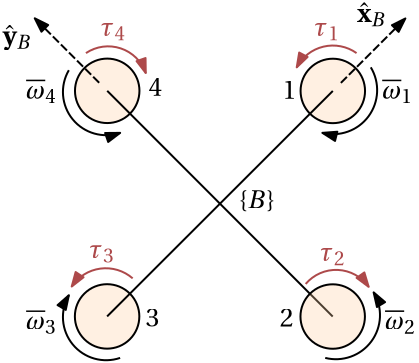

**Figure 9.6: **Top-down view of quadcopter with frame $\{B\}$ shown. Motor-propeller enumerations,directions, and resulting rotor torques are also shown.

With reference to Figure 9.6, the total torque about $\hat{\bf z}_B$ is a result of summing up all rotor torques based on Section 9.3.2. This is given by


$$\begin{array}{ll}
m_z
&=&\sum_{i=1}^4\tau_i,\\
&=& k_\tau\left(\overline\omega_1^2-\overline\omega_2^2+\overline\omega_3^2-\overline\omega_4^2\right),\\
&=&k_\tau\sum_{i=1}^4\left(-1\right)^{i+1}\overline\omega^2_i.
\end{array}$$


Note again that the torque produced by each rotor is in the direction opposite to the propeller's rotational direction. The resulting **torque vector **follows as


$${^B{\bf m}}= \left[\begin{array}{cccccccc}    m_x \\    m_y \\ m_z \end{array}\right],$$
  

which can also be written as a function of the rotor speeds by


$${^B{\bf m}}= \left[\begin{array}{cccccccc}    lk_f\left(\overline\omega^2_4-\overline\omega^2_2\right) \\    lk_f\left(\overline\omega^2_3-\overline\omega^2_1\right) \\ k_\tau(\left(\overline\omega_1^2-\overline\omega_2^2+\overline\omega_3^2-\overline\omega_4^2\right) \end{array}\right].$$
  

### 9.4.2 Rotational dynamics

Based on Euler's rotational equation, the **rotational dynamics **of a generalised rigid body is given by


$${\bf J}{^B\dot{\bf \omega}}+{^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right) = {^B{\bf m}},$$


where ${\bf J}$ is the symmetric, positive-definite inertia matrix, ${^B{\bf \omega}}$ describes the angular velocity of the rigid body in $\{B\}$, and ${^B{\bf m}}$ is the applied moment in $\{B\}$. While we are particularly interested in applying the equation above to a quadcopter, it is important to note that this equation applies to any rigid body under consideration. Robotics textbooks, such as *Modern Robotics*, provide a detailed derivation of the equation above. The second term in the equation above, namely ${^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right)$, is referred to as the centripetal moment and arises because we are describing the dynamics in $\{B\}$, which is a non-inertial reference frame. 

In reality, quadcopters will possess additional terms that contribute to the overall rotational acceleration of the platform. This includes:

- gyroscopic coupling, as a result of the angular momentum contained in each rotor,

- reactive moments, as a result of the propellers accelerating,

- blade flapping, of the rotating propeller blades experiences different airspeeds when in forward flight.

We will, however, only consider the simplified model given in the equation above. Quadcopters are purposefully designed to be have symmetric physical properties. As a result, the mass moment of inertia matrix, $\bf J$, is usually approximated as diagonal, with matching inertia terms about $\hat{\bf x}_B$ and $\hat{\bf y}_B$, namely


$${\bf J}\approx \left[\begin{array}{cccccccc}    J_{xx} & 0 & 0 \\    0 & J_{yy} & 0\\ 0 & 0 & J_{zz}  \end{array}\right]=\left[\begin{array}{cccccccc}    J_{xx} & 0 & 0 \\    0 & J_{xx} & 0\\ 0 & 0 & J_{zz}  \end{array}\right].$$


### 9.4.3 Obtaining orientation 

For the purposes of modelling and simulation, one needs to be able to solve Euler's rotational equation for rotational acceleration in order to ultimately determine the resulting orientation over time. If the applied moment, ${^B{\bf m}}(t)$, and current angular velocity, ${^B{\bf \omega}}(t)$, are known at time $t$, one can then solve for ${^B\dot{\bf \omega}}(t)$. The updated angular velocity at time $t+\Delta t$ is then obtained via integration of the rotational acceleration based on


$${^B{\bf \omega}}(t+\Delta t)={^B{\bf \omega}}(t)+\int_{t}^{t+\Delta t} {^B\dot{\bf \omega}}(t)dt.$$


Once the angular velocity has been determined, one can use the same procedure as developed in **Chapter 3** and **Chapter 4 **to determine orientation in rotation matrix or quaternion form. Recall that for exponential coordinates the rotation angle and vector are given by


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
        
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|}.$$


The corresponding incremental quaternion, describing the incremental rotation that took place over $\Delta t$ units of time, follows as


$$\begin{array}{cc}\Delta{\mathbf q} = \left[\begin{array}{cc}    \cos{\frac{\Delta\alpha}{2}} \\ \sin{\frac{\Delta\alpha}{2}} {^B\hat{\mathbf \omega}}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \\     \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_x \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_y \\    \sin{\frac{|{^B{\bf \omega}}|\Delta t}{2}} \hat{\omega}_z    \\ \end{array}\right].\end{array}$$


Finally, the absolute quaternion describing the updated pose of the quadcopter in $\{W\}$ is determined using


$${^W{\bf q}(t+\Delta t)={^W{\bf q}(t)\otimes \Delta {\bf q},$$
 

where ${^W{\bf q}(t)$ represents the orientation of the quadcopter prior to the incremental rotation taking place.

#### Example: Obtaining orientation from rotational dynamics

The example below generates a visualisation of the orientation behaviour over time as a result of specifying adjustable moments about the principal axes in $\{B\}$. You should hopefully be able to see that

- the rotational dynamics of a quadcopter are largely unstable!

- large velocities about $\hat{\bf z}_B$, as a result of large $m_z$ values, causes the UAV to go into a positive feedback cycle and increasingly build up velocity.

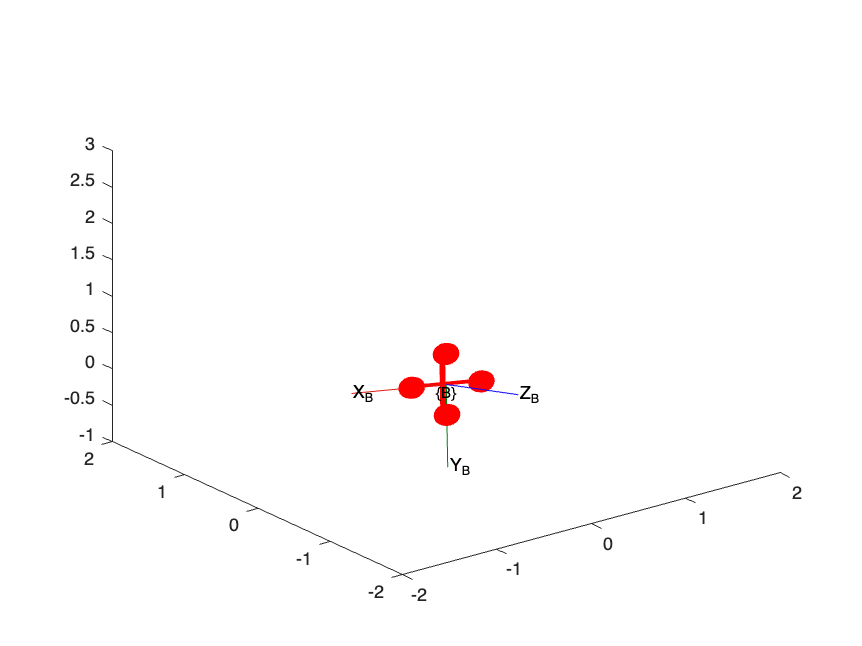

mx =-0.04;
my =0.01;
mz =-0.01;
m = [mx my mz]';

Jxx = 1e-2;
Jyy = Jxx;
Jzz = 5e-2;
J = diag( [Jxx,Jyy,Jzz] );

dT = 0.1;
w = [0 0 0]';
q = [1 0 0 0];

for i=1:3/dT
    w_dot = J\( m-cross(w,J*w) );
    w = w+dT*w_dot;

    alpha = norm(w)*dT;
    if( alpha==0 )
        v = [0 0 0]';
    else
        v = w/norm(w);
    end
    dq = [cos(alpha/2); sin(alpha/2)*v];
    q = quatmultiply(q,dq');

    figure(1),clf
    plotTransforms([0 0 0],q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
    xlim([-2 2]),ylim([-2 2]),zlim([-1 3])
    drawnow
    % pause(0.05)
    % axis equal,title('Before rotation')
end

We will show in **Chapter 10** how large velocities about $\hat{\bf z}_B$ are problematic for control design, based on coupling between $\hat{\bf z}_B$ and the other two principle axes. However, we will also explore simple ways to mitigate having velocities about $\hat{\bf z}_B$ without any perceivable downside.

### 9.4.4 Block diagram of rotational dynamics

The rotational dynamics of 


$${\bf J}{^B\dot{\bf \omega}}+{^B{\bf \omega}}\times \left( {\bf J} {^B{\bf \omega}} \right) = {^B{\bf m}},$$


including its dependence of rotor speed can be expressed up until the orientation level as shown in Figure 9.7, where


$${{\bf A}}  

= \left[\begin{array}{cccccccc}   

0 & -lk_f & 0 & lk_f \\
-lk_f &0 & lk_f & 0\\
k_\tau & -k_\tau & k_\tau & -k_\tau 
\end{array}\right],
$$


based on


$${^B{\bf m}}  
=\left[\begin{array}{cccccccc} m_x \\m_y\\m_z  \end{array}\right]
= \left[\begin{array}{cccccccc}   

0 & -lk_f & 0 & lk_f \\
-lk_f &0 & lk_f & 0\\
k_\tau & -k_\tau & k_\tau & -k_\tau 
\end{array}\right]
\left[\begin{array}{cccccccc} \overline\omega_1^2 \\ \overline\omega_2^2 \\ \overline\omega_3^2 \\ \overline\omega_4^2 \end{array}\right].$$


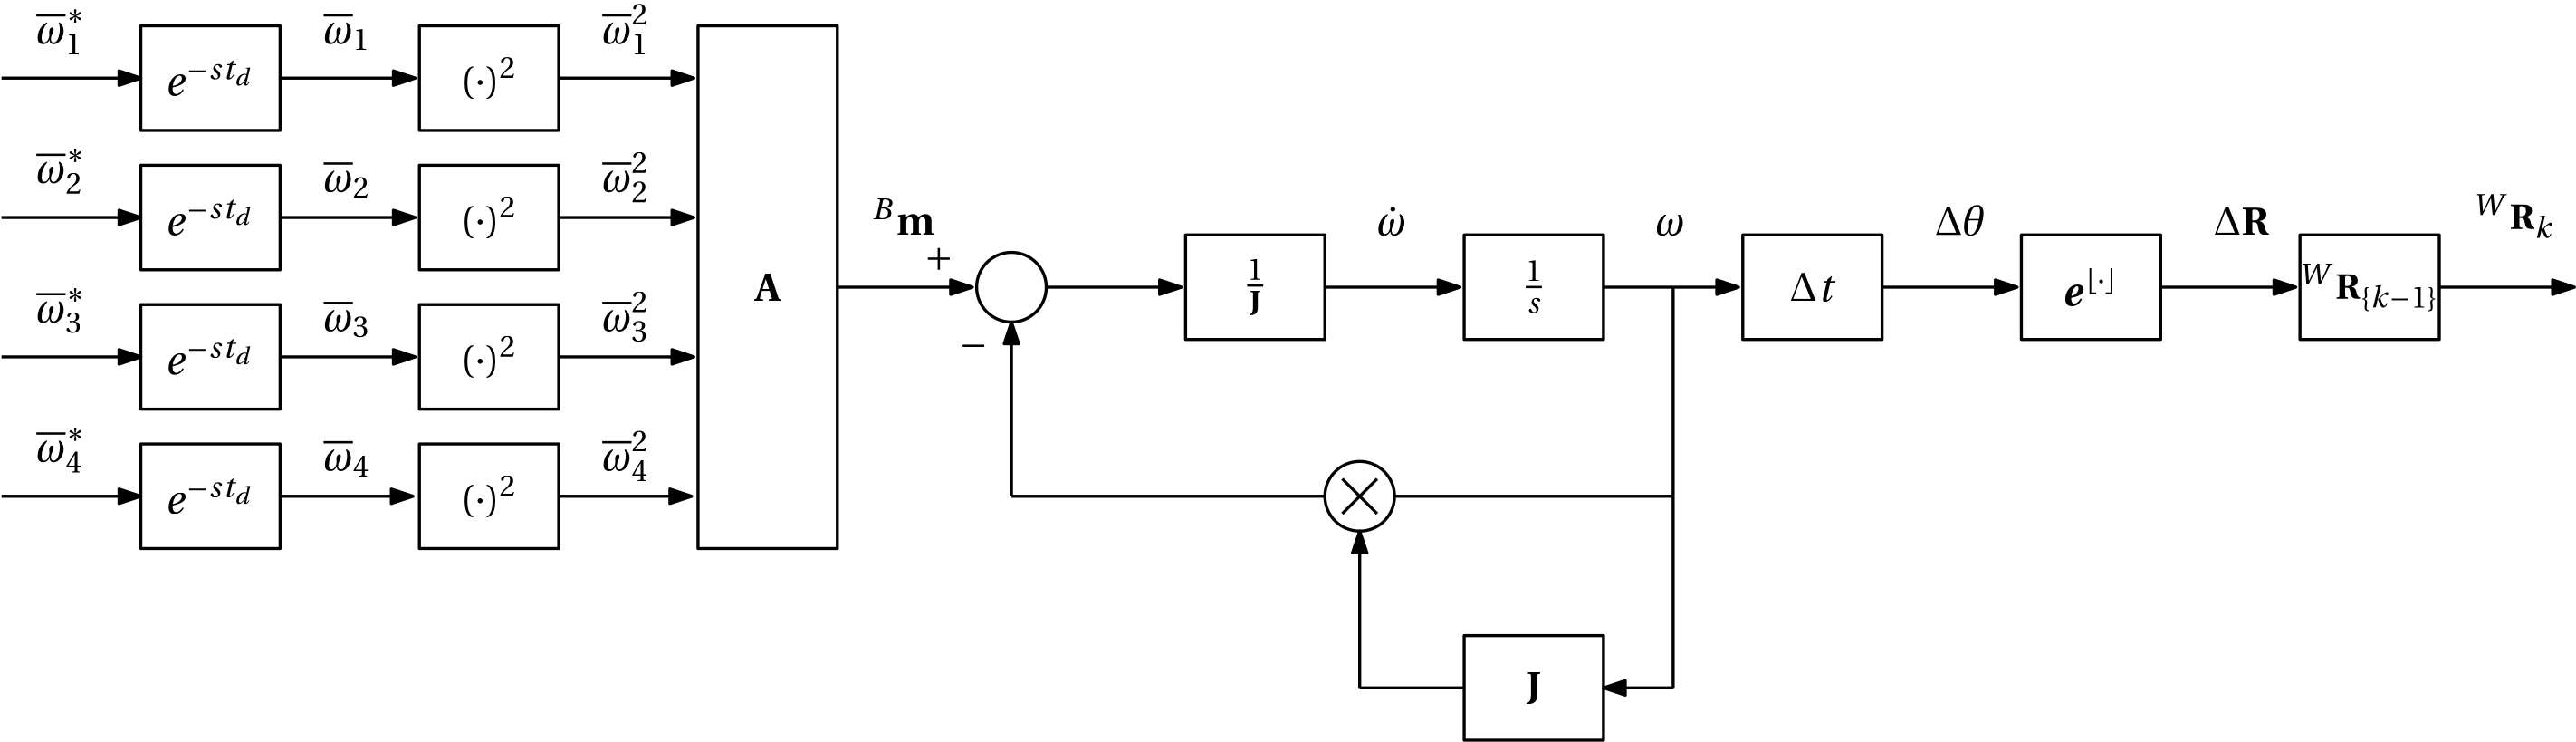

**Figure 9.7: **Block diagram representation of orientation dynamics, with desired motors speed as inputs and orientation as the output.

Note that the rotation matrix form of orientation update is only used for sake of notational convenience. In practice it would still be more pragmatic to make use of the quaternion counterpart.

## 9.5 Translational dynamics

The translational dynamics are dictated by two predominant forces:

- the thrust vector, which is made up of the net thrust produced by each rotor and directed based on the current orientation, and

- the gravitational thrust, which is known to be constant in the limited flying volume.

### 9.5.1 Thrust vector

Recall from Section 9.3.2 that the thrust produced by each rotor is given by 


$$f_i=k_f\overline\omega_i^2.$$


As all rotors have parallel rotational axes, the net thrust produced across all four rotors is given by


$$\begin{array}{ll}
f_\Sigma 
&=& f_1+f_2+f_3+f_4,\\
&=& \sum_{i=1}^4f_i,\\
&=& k_f\sum_{i=1}^4\overline\omega^2_i.\\
\end{array}$$


Based on this, it follows that the **thrust vector** in $\{B\}$ is given by


$$\begin{array}{ll}
{^B{\bf F}}
&=&\left[\begin{array}{cccccccc}    0 & 0 & f_\Sigma   \end{array}\right]^T,\\
&=&\left[\begin{array}{cccccccc}    0 & 0 &  k_f\sum_{i=1}^4\overline\omega^2_i  \end{array}\right]^T.

\end{array}$$


Notably, the thrust produced by a (conventional) quadcopter will always be parallel to $\hat{\bf z}_B$. The thrust vector in $\{W\}$ is determined by


$${^W{\bf F}}={^W{\bf R}_B}{^B{\bf F},$$


where ${^W{\bf R}_B}\in \text{SO(3)}$ is the rotation matrix describing the orientation of $\{B\}$with respect to $\{W\}$.

### 9.5.2 Gravitational force

As previously explored, gravity is known to act anti-parallel to $\hat{\bf z}_W$ with a magnitude of $g\approx 9.8$ in Cape Town, South Africa. It follows that the gravitational force vector in $\{W\}$ is given by


$${^W{\bf G}}=\left[\begin{array}{cccccccc}    0 & 0 & -mg   \end{array}\right]^T,$$


where $m$ defines the total mass of the rigid body.

### 9.5.3 Translational motion

The **translational motion** in $\{W\}$ is governed by Newton's second law and is given by


$$m{^W\ddot{\bf p}}= {^W{\bf F}}+{^W{\bf G},$$


where ${^W\ddot{\bf p}}$ is the translational acceleration of the quadcopter, $^W{\bf F}$ is the thrust vector produced by the quadcopter rotors, and ${^W{\bf G}}$ is the gravitational force. It is often more convenient to express the translational motion as a function of body-frame thrust vector, namely


$$m{^W\ddot{\bf p}}= {^W{\bf R}_B}{^B{\bf F}+{^W{\bf G},$$


which shows the clear dependence on having to vector the thrust using the orientation in order to create rectilinear motion. Note that the equation above ignores certain real-world effects, such as:

- ground effect, which is the apparent increase of thrust when the quadcopter near the ground, and

- aerodynamic drag, as a result of the non-ideal profile of the quadcopter body when in motion.

We will assume in this course that the above two factors are negligible, which is a fair assumption when the quadcopter is sufficiently far from a physical surface and moving slowly. 

The translational dynamics of the quadcopter can also be modelled in $\{B\}$ instead of $\{W\}$. We will, however, only use the form above for this course.

### 9.5.4 Obtaining position

Analogous to Section 9.4.3, the quadcopter position over time can be determined from the equations above using integration, where


$${^W\dot{\bf p}}(t)={^W\dot{\bf p}}(0)+\int_0^t {^W\ddot{\bf p}}(t) dt,$$


and


$${^W{\bf p}}(t)={^W{\bf p}}(0)+\int_0^t {^W\dot{\bf p}}(t) dt.$$


As with obtaining orientation from the rotational dynamics, this process is useful when we want to simulate a quadcopter in software to get a better understanding of the system.

#### Example: Obtaining position from translational dynamics

The example below generates a visualisation of the position behaviour over time as a result of altering the orientation. As with the rotational dynamics, the translational motion of a quadcopter is largely unstable!

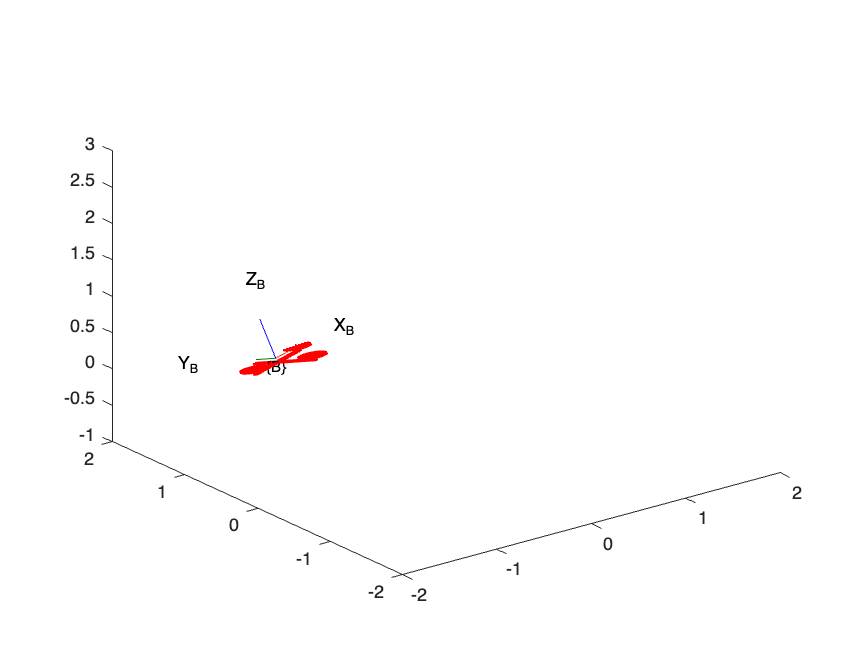

alpha =-32*pi/180;
vx =0.5;
vy =0;
vz =-0.6;
v = [vx vy vz]';
if( norm(v)==0 )
    v = [0 0 0]';
else
    v = v/norm(v);
end

q = [cos(alpha/2) sin(alpha/2)*v'];
R = quat2rotm(q);

g = 9.8;
m = 0.5;
Gw = [0 0 -m*g]';
Fb = [0 0 m*g]';

dT = 0.1;

p_dot = 0;
p = 0;
for i=1:1/dT
    
    Fw = R*Fb;
    p_ddot = 1/m*(Fw+Gw);
    p_dot = p_dot+dT*p_ddot;
    p = p+dT*p_dot;

    figure(1),clf
    plotTransforms(p',q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
    xlim([-2 2]),ylim([-2 2]),zlim([-1 3])
    drawnow
    % pause(0.05)
    % axis equal,title('Before rotation')
end

### 9.5.5 Block diagram of translational dynamics

The translational dynamics of 


$$m{^W\ddot{\bf p}}= {^W{\bf R}_B}{^B{\bf F}+{^W{\bf G},$$


are represented in the block diagram shown in Figure 9.8, which includes consideration for the desired angular velocities as the inputs to the system. 

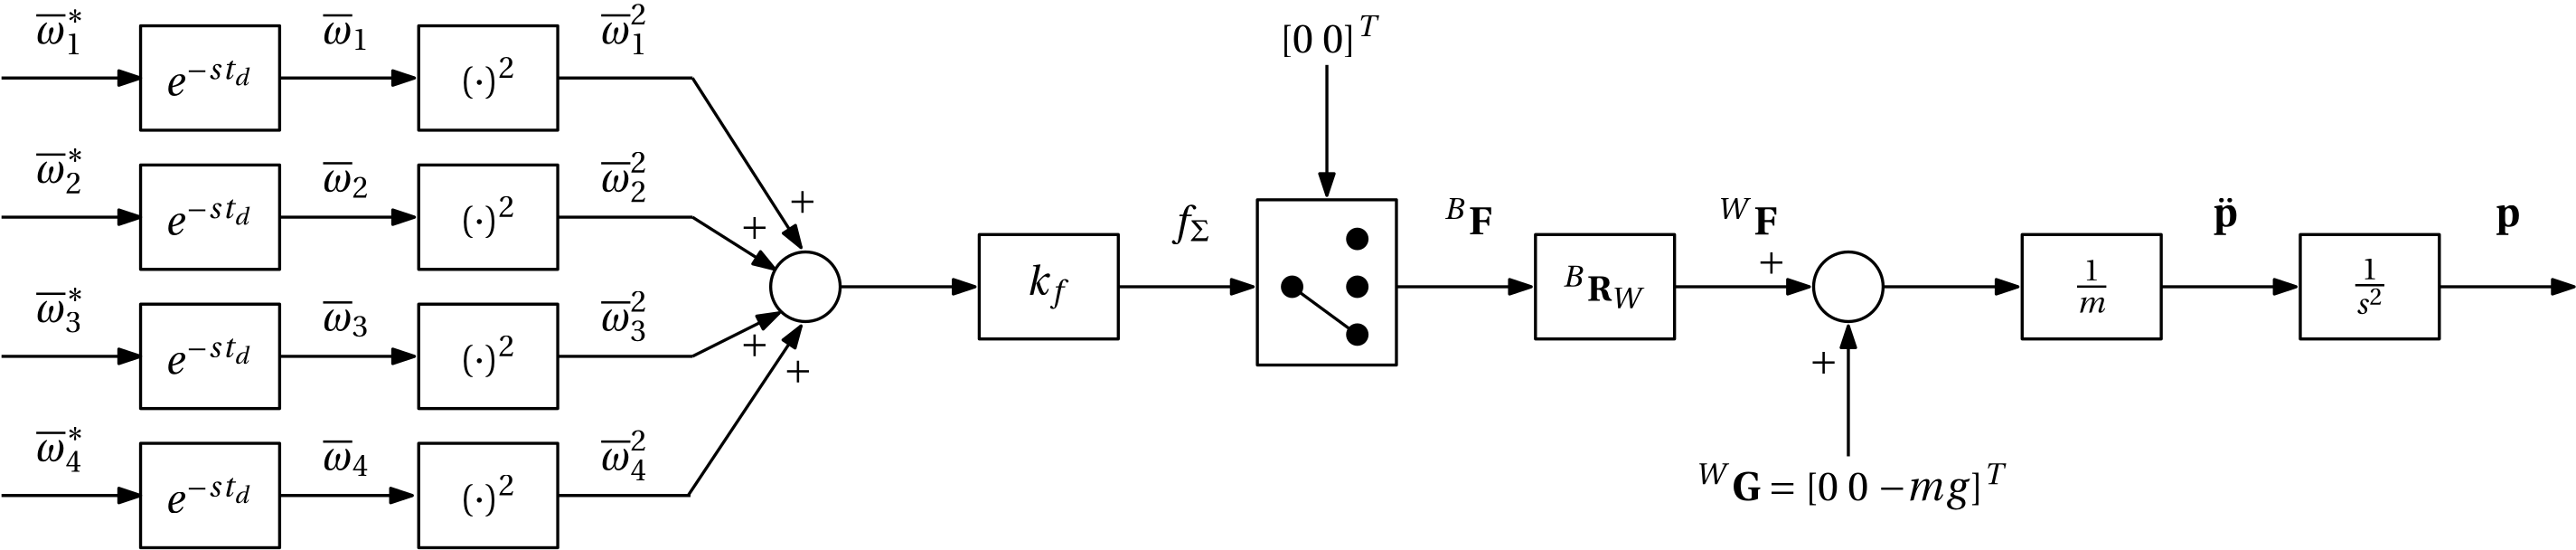

**Figure 9.8: **Block diagram representation of translational dynamics, with desired motors speed as inputs and position as the output.

Note that the orientation dynamics described in Figure 9.7 would naturally affect the translational behaviour shown above, based on the requirement of the rotation matrix ${^B{\bf R}_W}$ in order to rotate $^B{\bf F}$ into $\{W\}$.

## 9.6 Hover conditions

The quadcopter is in a state of idealised **hover** when the thrust vector $^W{\bf F}$ is equivalent and anti-parallel to the gravitational force ${^W{\bf G}}$. In addition, the quadcopter must be at a null rotation and not experiencing any rotational or translational velocities. In this case, the quadcopter is able to maintain at a fixed point in $\{W\}$. Under ideal conditions (with all motor-propeller subsystems identical and no external forces or moments acting on the quadcopter), each rotor will be supplying a quarter of the force required to counteract gravity. This hover thrust quantity per rotor is given by


$$f_h=\frac{mg}{4},$$


where $m$ is the mass of the quadcopter. Based on the rotor thrust model from Section 9.3.2, this implies that all motor speeds at hover are equal in magnitude and given by


$$\begin{array}{ll}
\overline\omega_h
&=&\sqrt{\frac{f_h}{k_f}},\\
&=&\sqrt{\frac{mg}{4k_f}}.
\end{array}$$


In this case, the control moment from Section 9.4.1 becomes


$${\bf m}_h=\left[0~~0~~0\right]^T,$$


which implies that the quadcopter should not be experiencing any rotational acceleration. In reality, minor mismatch between the four motors and propellers, as well as external disturbances, such as from the wind, means that the idealised conditions above are not exact.

#### Example: Quadcopter in idealised hover

The example below generates a visualisation of the quadcopter in an idealised hover, which is possible when there is a null rotation, the gravitational force is balanced by the rotor thrust, and there is no velocity being experienced by the quadcopter.

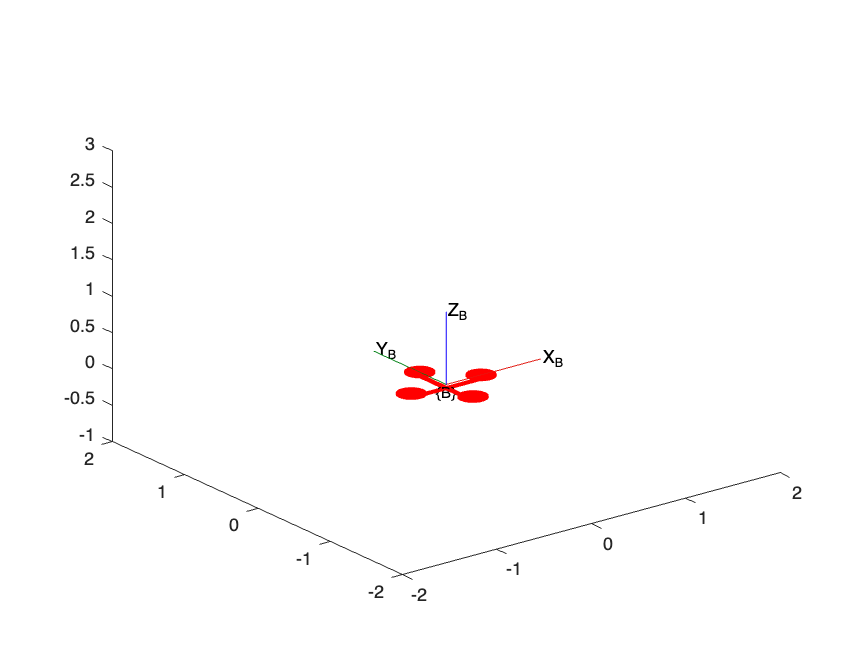

q = [1 0 0 0];
R = quat2rotm(q);

g = 9.8;
m = 0.5;
Gw = [0 0 -m*g]';
Fb = [0 0 m*g]';

dT = 0.1;

p_dot = 0;
p = 0;
for i=1:3/dT
    
    Fw = R*Fb;
    p_ddot = 1/m*(Fw+Gw);
    p_dot = p_dot+dT*p_ddot;
    p = p+dT*p_dot;

    figure(1),clf
    plotTransforms(p',q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
    xlim([-2 2]),ylim([-2 2]),zlim([-1 3])
    drawnow
end

## 9.7 Actuation

### 9.7.1 Under-actuated systems

Recall that the actuator space, $\mathcal{A}$, describes the space of all actuators affecting change on a particular robotic platform. In the case of the quadcopter, the actuator space is 4-dimensional


$$\text{dim}~\mathcal{A}=4,$$


as the quadcopter has four motor-propeller subsystems that can adjust thrust and torque. Given that there are no joint constraints on a quadcopter, its configuration space is $\mathcal{C}\in \text{SE(3)}$, which implies that the number of degrees of freedom is given by


$$N=\text{dim}~\mathcal{C}=6.$$


In the case that a robot has less actuators than the number of degrees of freedom, as in the case of the quadcopter, we term the robot as an **under-actuated system**. This condition is given by


$$\text{dim}~\mathcal{A}<N.$$


Somewhat similar to non-holonomic robots, this means that one cannot independently control all pose elements that make up the C-space. In the case of the quadcopter, we see that translation in the $\hat{\bf x}_W$-$\hat{\bf y}_W$ plane is only possible if the quadcopter first "pitches forward", which allows the thrust vector to not simply point in the direction of $\hat{\bf z}_W$. As such, a manoeuvre is required to access $\hat{\bf x}_W$-$\hat{\bf y}_W$ plane motion. This means that roll and pitch are naturally coupled to translational motion. For this reason, quadcopters are also classed as non-holonomic, as quadcopters cannot instantaneously accelerate forwards — they have to first pitch forward, which then subsequently allows for forward acceleration.

A differentially-steered robot is another example of an under-actuated system, as it possesses two actuators (in the form of two motors), but has three degrees of freedom.

### 9.7.2 Fully-actuated systems

In the case that the number of actuators is equal to the number of degrees of freedom of the robot, given by 


$$\text{dim}~\mathcal{A}=N,$$


the robot is classed as a **fully-actuated system**. An example of a fully-actuated system is a 2R robot.